# **Lesson III.6:   The Singular Value Decomposition I**

**The SVD.**    In this lesson and the next, the basic mechanics and elementary properties of the singular value decomposition (SVD) are considered.    

If $A$is a real $m\times n$ matrix, then 

        (III.6.1)            $A=U\Sigma V^T$ 

where

- $U
$ is an $m\times m$ orthogonal matrix,

- $\Sigma$ is a $m\times n$ "diagonal" matrix with nonnegative entries monotonically decreasing down the diagonal,

- $V$ is an $n\times n$ orthogonal matrix.

The $m\times n$ matrix $\Sigma$ is diagonal in the sense that $\Sigma_{ij}=0$ for $i\ne j$.  If $r=\text{rank}(A)$ then the first $r$ diagonal elements satisfy

     (III.6.2)        $\Sigma_{11}\ge\Sigma_{22}\ge \cdots \ge \Sigma_{rr}>0.
$

Any diagonal element besides these $r$ entries is 0.   The nonzero diagonal entries of $\Sigma$ are known as the ***singular values*** of $A$.   

     (III.6.3)       $\Sigma = \left[\matrix{
\sigma_1&&& & 0 & \cdots &0\cr
 &\sigma_2&& & \vdots & & \vdots\cr 
&&\ddots& & \vdots &  & \vdots \cr
 &&&\sigma_r&0&\cdots&0\cr
0&\cdots&\cdots &0 & 0 & \cdots & 0 \cr
\vdots & & &\vdots & \vdots & & \vdots \cr
0&\cdots&\cdots &0 & 0 & \cdots & 0 \cr
}\right]$        where $\sigma_1\ge\sigma_2\ge\cdots\ge \sigma_r>0$.   Note:  All singular values (if any) are positive.

**Example III.6.1:   **Consider $A=\left[\matrix{4&3\cr 3 & 4}\right]$.    An SVD for $A$ consists of $U=V=\frac{\sqrt{2}}{2}\left[\matrix{1 &1\cr 1&-1}\right]$and $\Sigma=\left[\matrix{7 & 0 \cr 0 & 1}\right]$.   Note: for a symmetric matrix with positive eigenvalues, an SVD is an orthogonal diagonalization where the eigenvalues have been ordered from largest to smallest.

**Example III.6.2:   **Consider $A=\left[\matrix{1 & 3 \cr 2 & -3 \cr 3 & 1}\right]$.  An SVD for $A$ consists of 

        $U=\left[\matrix{\frac{3}{\sqrt{19}}&\frac{1}{\sqrt{14}}&-\frac{11}{\sqrt{266}}\cr
-\frac{3}{\sqrt{19}}& \sqrt{\frac{2}{7}}&-4\sqrt{\frac{2}{133}}\cr
\frac{1}{\sqrt{19}}&\frac{3}{\sqrt{14}}&\frac{9}{\sqrt{266}}

}\right]$,        $\Sigma=\left[\matrix{\sqrt{19} & 0\cr0 & \sqrt{14}\cr0 &0}\right]$,    and     $V=\left[\matrix{0 & 1\cr 1 & 0 }\right]$.

This example illustrates one of the less attractive features of the SVD:   exact expressions for the factors have a tendency to be somewhat complicated.   

**Example III.6.3:  **To see how complicated these expressions can become, note that if we change just the lower righthand element of this matrix to zero then 

   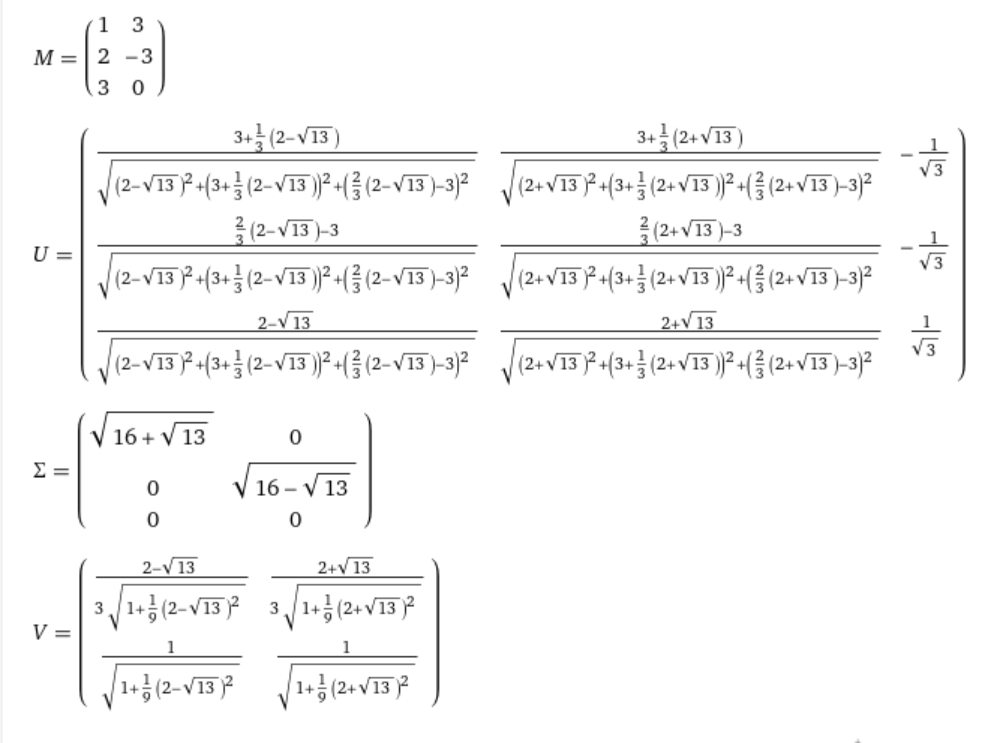     

The calculation above was performed by WolframAlpha.    Exam problems are generally chosen with extreme care so as to be tractable.   In application, the exact factorization is rarely of particular significance or interest.   Numerical computation/approximation, along with understanding of the factorization, typically powers applications.    

**An approach to computation.**   If $A=U\Sigma V^T$then the Gram matrix of $A$ gives

       (III.6.4)      $A^TA=\big(U\Sigma V^T\big)^T\big(U\Sigma V^T\big)=V\Sigma^TU^T U\Sigma V^T=V\big(\Sigma^T\Sigma\big) V^T$.

Here we note that $\Sigma^T\Sigma$ is an $n\times n$ matrix with the squares of the singular values on the main diagonal:

      (III.6.5)      $\Sigma^T\Sigma = \left[\matrix{
\sigma_1^2 & & & &&&\cr
 &\sigma_2^2& &&&&\cr
&&\ddots&&&&\cr
&&&\sigma_r^2&&&\cr
&&&&0&&\cr
&&&&&\ddots&\cr
&&&&&&0
}\right]$ . 

In particular, $\Sigma^T\Sigma$ is diagonal.   Hence, orthogonal diagonalization of the Gram matrix $A^TA$ essential gives the orthogonal matrix $V$and the singular values which are the square roots of the nonzero eigenvalues of the Gram matrix $A^TA$.   Of course, it is necessary to arrange the eigenvalues (along with their eigenvectors) in decreasing order.

Once $V$ and $\Sigma$ are found through orthogonal diagonalization of $A^TA$, it remains to find $U$.  The first step is to multiply the basic factorization (III.6.1) on the right by $V$ to give $AV=U\Sigma$.   Written out column-by-column with $V=\left[\matrix{{\bf v}_1 &\cdots &{\bf v}_n}\right]$and  $U=\left[\matrix{{\bf u}_1 &\cdots &{\bf u}_m}\right]$,

    (III.6.6)    $AV=A\left[\matrix{{\bf v}_1&\cdots&{\bf v}_n}\right]=\left[\matrix{A{\bf v}_1&\cdots&A{\bf v}_n}\right]$    and     $U\Sigma=\left[\matrix{{\bf u}_1&\cdots&{\bf u}_m}\right]\Sigma=\left[\matrix{\sigma_1{\bf u}_1&\cdots&{\sigma_r}{\bf u}_r&{\bf 0}&\cdots &{\bf 0}}\right]$.

Note:   the two matrices in (III.6.6) are $m\times n$.  Hence,

    (III.6.7a)    ${\bf u}_\ell=\frac{1}{\sigma_\ell}A{\bf v}_\ell$    for    $\ell=1,\dots,r$     and

    (III.6.7b)    $A{\bf v}_\ell={\bf 0}$    for     $\ell=r+1,\cdots,n$.

The first of these equations gives the means for finding the first $r$ columns of $U$.  It also shows that these $r$ columns are an orthonormal basis for $\text{col}(A)$, the column space of $A$.  Hence, the remaining column are an orthonormal basis for the orthogonal complement of $\text{col}(A)$ which is $\text{nul}(A^T)$.   Thus, the remaining columns of $U$ may be computed as an orthonormal basis for $\text{nul}(A^T)$.

**A three-step process for construction of the SVD.**

- Compute the orthogonal diagonalization of the Gram matrix $A^TA=VDV^T$ and use the $r$ singular values (the square roots of the nonzero eigenvalues in $D$) to construct the $m\times n$ matrix $\Sigma$.   

- Use (III.6.7a) to compute the first $r$ columns of $U$.

- Find the remaining columns of $U$as an orthonormal basis of $\text{nul}(A^T)$. (This likely involves the use of Gram-Schmidt in some way).

**Example III.6.3:  **Find the SVD for $A=\left[\matrix{1 & 2\cr 2 & -2 \cr 2 & 1}\right]$.    

Step 1:     $A^TA=\left[\matrix{1&2&2\cr 2& -2 & 1}\right]\left[\matrix{1 & 2\cr 2& -2 \cr 2 & 1}\right]=\left[\matrix{9 &0\cr0 & 9}\right]=\left[\matrix{1&0\cr0&1}\right]\left[\matrix{9 &0\cr0 & 9}\right]\left[\matrix{1&0\cr0&1}\right]$.

            $\Rightarrow\qquad V=\left[\matrix{1&0\cr0&1}\right]$    and    $\Sigma=\left[\matrix{3&0\cr0&3\cr0&0}\right]$.

Step 2:     ${\bf u}_1=\frac{1}{\sigma_1}A{\bf v}_1=\frac13\left[\matrix{1 & 2\cr 2 & -2\cr 2 & 1}\right]\left[\matrix{1\cr 0}\right]=\left[\matrix{1/3\cr2/3\cr2/3}\right]$    and     ${\bf u}_2=\frac{1}{\sigma_2}A{\bf v}_2=\frac13\left[\matrix{1 & 2\cr 2 & -2\cr 2 & 1}\right]\left[\matrix{0\cr 1}\right]=\left[\matrix{2/3\cr-2/3\cr1/3}\right]$.

Step 3:    $A^T=\matrix{\bullet \cr 2}~\left[\matrix{1 & 2 & 2 \cr 2 & -2 &1}\right] \sim 
\matrix{~ \cr \times -1/6}~\left[\matrix{1 & 2 & 2 \cr 0 & -6 &-3}\right]\sim
\matrix{2\cr\bullet}~
\left[\matrix{1&2&2\cr0&1&1/2}\right]\sim
\left[\matrix{1&0&1\cr 0 & 1 & 1/2}\right]
$

            $\Rightarrow\qquad {\bf u}_3=\left[\matrix{-1\cr-1/2\cr 1}\right]$    but Gram-Schmidt    $\Rightarrow\qquad {\bf u}_3=\frac13\left[\matrix{-2\cr -1\cr 2}\right]$

            
$$\Rightarrow\qquad U=\frac13 \left[\matrix{
1 & 2 & -2\cr 2 &-2 & -1\cr 2 & 1 & 2}\right]$$


If we repeat this calculation in MATLAB, we find some variations.

format rat
[U,Sigma,V]=svd([1 2; 2 -2; 2 1])

U =       -1/3           -2/3           -2/3     
      -2/3            2/3           -1/3     
      -2/3           -1/3            2/3     


Sigma =        3              0       
       0              3       
       0              0       


V =       -1              0       
       0             -1       


Notice there are some choices in the construction process, including sign choices for eigenvectors.  The presence of choices means that there is typically more than one SVD for a given matrix.    It should be noted, however, that the singular values will be shared by all of them.

**Example III.6.2:**   We revisit an earlier example but this time working through the construction procedure (letting MATLAB do the heavy lifting):

A=[1 3; 2 -3; 3 1];
G=A'*A                  % our Gram matrix which is conveniently diagoal :)

G =       14              0       
       0             19       


[V,D]=eig(sym(G))       % "sym" induces MATLAB to perform symbolic computations

$$V = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} 14 & 0\\ 0 & 19 \end{array}\right)$$

D = [0 1; 1 0]*D*[0 1; 1 0]   % using an exchange matrix to reorder the eigenvalues

$$D = \left(\begin{array}{cc} 19 & 0\\ 0 & 14 \end{array}\right)$$

V = V*[0 1; 1 0]              % reordering the eigenvectors accordingly

$$V = \left(\begin{array}{cc} 0 & 1\\ 1 & 0 \end{array}\right)$$

SS=sqrtm(sym(D))              % finding the heart of the signular value matrix

$$SS = \left(\begin{array}{cc} \sqrt{19} & 0\\ 0 & \sqrt{14} \end{array}\right)$$

Sigma=sym(zeros(3,2));        % constructing the body of Sigma
Sigma(1:2,1:2)=SS             % endowing Sigma with its heart

$$Sigma = \left(\begin{array}{cc} \sqrt{19} & 0\\ 0 & \sqrt{14}\\ 0 & 0 \end{array}\right)$$

Ucol=A*V(:,1:2)*inv(SS)       % computing the first r=2 columns of U

$$Ucol = \left(\begin{array}{cc} \frac{3\,\sqrt{19}}{19} & \frac{\sqrt{14}}{14}\\ -\frac{3\,\sqrt{19}}{19} & \frac{\sqrt{14}}{7}\\ \frac{\sqrt{19}}{19} & \frac{3\,\sqrt{14}}{14} \end{array}\right)$$

u3=null(sym(A)')             % basis for the left null space

$$u3 = \left(\begin{array}{c} -\frac{11}{9}\\ -\frac{8}{9}\\ 1 \end{array}\right)$$

u3=u3/sqrt(u3'*u3)      % again Gram-Schmidt (normalization only)

$$u3 = \left(\begin{array}{c} -\frac{11\,\sqrt{266}}{266}\\ -\frac{4\,\sqrt{266}}{133}\\ \frac{9\,\sqrt{266}}{266} \end{array}\right)$$

U=[Ucol u3]

$$U = \left(\begin{array}{ccc} \frac{3\,\sqrt{19}}{19} & \frac{\sqrt{14}}{14} & -\frac{11\,\sqrt{266}}{266}\\ -\frac{3\,\sqrt{19}}{19} & \frac{\sqrt{14}}{7} & -\frac{4\,\sqrt{266}}{133}\\ \frac{\sqrt{19}}{19} & \frac{3\,\sqrt{14}}{14} & \frac{9\,\sqrt{266}}{266} \end{array}\right)$$

U*U'                % checking U is orthogonal

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

U*Sigma*V'          % checking the SVD factorization

$$ans = \left(\begin{array}{cc} 1 & 3\\ 2 & -3\\ 3 & 1 \end{array}\right)$$

**The SVD of the transpose.   **Suppose that the SVD of a matrix is given:  $A=U\Sigma V^T$.   How does one compute the SVD of the transpose $A^T$?   The easy answer is to take the transpose of the SVD:

        (III.6.7)    $A^T=\big(U\Sigma V^T\big)^T =V\Sigma^T U^T$.

That is, $U$and $V$ swap roles and $\Sigma$ is unchanged except for rearranging some of the zeros that pad the diagonal entries.   For example, 

        $\left[\matrix{2&5&4\cr 6&3&0}\right]=\left[\matrix{\sqrt{2}/2 & \sqrt{2}/2 \cr \sqrt{2}/2 &-\sqrt{2}/2}\right]
\left[\matrix{6\sqrt{2} &0 &0\cr0&3\sqrt{2}&0}\right]\left[\matrix{-2/3 & 2/3&1/3\cr -2/3&-1/3&-2/3\cr -1/3& -2/3&2/3}\right]^T$    and

            $\left[\matrix{2&6\cr5&3\cr4&0 }\right]=
\left[\matrix{-2/3 & 2/3&1/3\cr -2/3&-1/3&-2/3\cr -1/3& -2/3&2/3}\right]
\left[\matrix{6\sqrt{2}&0 \cr0&3\sqrt{2}\cr0&0}\right]
\left[\matrix{\sqrt{2}/2 & \sqrt{2}/2 \cr \sqrt{2}/2 &-\sqrt{2}/2}\right]^T$.

This reflects the important result that the Gram matrix of $A$ (i.e., $A^TA$) and the Gram matrix of $A^T$ (i.e., $AA^T$) share the same nonzero eigenvalues (even though they may have completely different dimensions).

An alternative to the procedure outlined above for constructing the SVD has thus emerged.   Namely, we apply the procedure to the transpose and then swap $U$ and $V$ and reshape $\Sigma$ appropriately.   One reason for choosing one approach over the other is that the size of $A^TA$ is $n\times n$ while the size of $AA^T$is $m\times m$.   Often choosing according to which dimension is smaller can make the initial orthogonal diagonalization more tractable.   For example,

        
$$A=\left[\matrix{1&1&1&1&0&0\cr1&-1&0&0&1&1}\right]\qquad\Rightarrow\qquad
A^TA=
\left[\matrix{1&1\cr1&-1\cr1&0\cr1&0\cr 0&1\cr 0&1\cr}\right]\left[\matrix{1&1&1&1&0&0\cr1&-1&0&0&1&1}\right]=\left[\matrix{2&0&1&1&1&1\cr 0&2&1&1&-1&-1\cr 1&1&1&1&0&0\cr1&1&1&1&0&0\cr 1&-1&0&0&1&1\cr1&-1&0&0&1&1}\right]$$


and mere mortals are likely to fall into despair.    But the Gram matrix of the transpose is far less intimidating:

                                  $AA^T=\left[\matrix{1&1&1&1&0&0\cr1&-1&0&0&1&1}\right]\left[\matrix{1&1\cr1&-1\cr1&0\cr1&0\cr 0&1\cr 0&1\cr}\right]=\left[\matrix{4&0\cr0&4}\right]$.

If we wish to proceed with the direct diagonalization of $A^TA$, we are now in a far better position as we know that the eigenvalues are $\lambda_1=4,~\lambda_2=4,~\lambda_3=0,\lambda_4=0,\lambda_5=0,\lambda_6=0$.

**The SVD of an orthogonal matrix.    **If $A$ is an orthogonal matrix, some of the possible singular value decompositions of $A=U\Sigma \;V^T$include 

- $U=A,~\Sigma=I,~V=I$,

- $U=I,~\Sigma=I,~V=A^T$,

- $U=A^2,~\Sigma=I,~V=A$,

- $U=A^T,~\Sigma=I,~V=A^{2T}$.

There are of course infinitely many more, but simplicity suggests a reason for some bias favoring the first.

**The SVD of a real symmetric matrix.  **For an $n\times n$ real symmetric matrix $A,$ there is always an orthogonal diagonalization:

         (III.6.8a)       $A=VDV^T$

where we are free to order the eigenvalues with decreasing magnitudes.

         (III.6.8b)        $|\lambda_1|\ge|\lambda_2|\ge\cdots\ge|\lambda_n|$.

If the eigenvalues of $A$ are nonnegative, then this orthogonal diagonalization is also an SVD of $A$ where $U=V$.   For example,

                $\left[\matrix{4&1\cr1&4}\right]=\left[\matrix{\sqrt{2}/2 & \sqrt{2}/2\cr\sqrt{2}/2&-\sqrt{2}/2}\right]\left[\matrix{5&0\cr0&3}\right]
\left[\matrix{\sqrt{2}/2 & \sqrt{2}/2\cr\sqrt{2}/2&-\sqrt{2}/2}\right]^T$.

In case, $A$ has one or more negative eigenvalues an extra step is needed.    Specifically, we factor $D$ as $W\Sigma$ where

-  $W$ is an $n\times n$diagonal matrix where the $\ell^\text{th}$ diagonal element is 1 if the $\ell^\text{th}$ element of the diagonal of $D$ is nonnegative and -1 if the $\ell^\text{th}$ element of the diagonal of $D$ is negative and 

- $\Sigma$ has the absolute values of the eigenvalues of $D$ on its diagonal.   

For example, 

  $D=\left[\matrix{7 &0&0&0&0\cr 0&-6&0&0&0\cr0&0&-4&0&0\cr0&0&0&3&0\cr0&0&0&0&0}\right]=W\Sigma
}$    where    $W=\left[\matrix{
1&0&0&0&0\cr
0&-1&0&0&0\cr
0&0&-1&0&0\cr
0&0&0&1&0\cr
0&0&0&0&1}\right]$    and     $\Sigma=\left[\matrix{7 &0&0&0&0\cr 0&6&0&0&0\cr0&0&4&0&0\cr0&0&0&3&0\cr0&0&0&0&0}\right]$.

In brief, we have factored the signs of the eigenvalues out of $D$.   Thus, we have $A=VW\Sigma V^T$and letting $U=VW$ we have an SVD for $A$.   We have of course used the fact that $W$is an orthogonal matrix to assure that $U$ is orthogonal.    Here is an example of converting an orthogonal diagonalization to an SVD:

                
$$\matrix{
\left[\matrix{1&4\cr4&1}\right]&=&\left[\matrix{\sqrt{2}/2 & \sqrt{2}/2\cr\sqrt{2}/2&-\sqrt{2}/2}\right]\left[\matrix{5&0\cr0&-3}\right]
\left[\matrix{\sqrt{2}/2 & \sqrt{2}/2\cr\sqrt{2}/2&-\sqrt{2}/2}\right]^T\qquad\quad\cr
&=&\left[\matrix{\sqrt{2}/2 & \sqrt{2}/2\cr\sqrt{2}/2&-\sqrt{2}/2}\right ]
  \left[\matrix{1&0\cr0&-1}\right]   \left[\matrix{5&0\cr0&3}\right]
\left[\matrix{\sqrt{2}/2 & \sqrt{2}/2\cr\sqrt{2}/2&-\sqrt{2}/2}\right]^T\cr
&=&\left[\matrix{\sqrt{2}/2 & -\sqrt{2}/2\cr\sqrt{2}/2&\sqrt{2}/2}\right]\left[\matrix{5&0\cr0&3}\right]
\left[\matrix{\sqrt{2}/2 & \sqrt{2}/2\cr\sqrt{2}/2&-\sqrt{2}/2}\right]^T\qquad\quad\cr
}$$


Hence, the orthogonal diagonalization of a real symmetric matrix is easily converted into the SVD of the same matrix.   

**Follow-up Problems**

**Problem III.6.1:  **Find an SVD for each of the following matrices:


$$\qquad\text{(a)}\quad \left[\matrix{1\cr 2}\right]\qquad\text{(b)}\quad \left[\matrix{
2&1\cr1&2}\right]\qquad
\text{(c)}\quad \left[\matrix{
1&2\cr2&1}\right]\qquad
\text{(d)}\quad \left[\matrix{
1&-3\cr3&1}\right]\qquad
\text{(e)}\quad \left[\matrix{
3&4\cr4&-3}\right]\qquad$$


**Problem III.6.2:  **Find an SVD for each of the following matrices:


$$\qquad\text{(a)}\quad \left[\matrix{1\cr 2\cr 3}\right]\qquad
\text{(b)}\quad \left[\matrix{
3&2&1}\right]\qquad
\text{(c)}\quad \left[\matrix{
1&1\cr1&-2\cr1&1}\right]\qquad
\text{(d)}\quad \left[\matrix{
1&-3\cr3&1\cr0&0}\right]\qquad
$$


**Problem III.6.3:  **Using WolframAlpha find an exact SVD of $\left[\matrix{1&2&3\cr4&5&6\cr7&8&9}\right]$.  

Hint:  svd {{1,2,3},{4,5,6},{7,8,9}} 

**Problem III.6.4:   **Leaning on MATLAB to do the heavy lifting, find an exact SVD of the following matrices:


$$\qquad\text{(a)}\quad \left[\matrix{2&1&0&1\cr1&2&1&0\cr0&1&2&1\cr1&0&1&2}\right]\qquad\qquad
\text{(b)}\quad\left[\matrix{1&1&1&1&1\cr 1&1&1&1&1\cr 1&1&1&1&1 \cr 1&1&1&1&1}\right]$$


**Problem III.6.5:**   Find an SVD of $\left[\matrix{a&b\cr b &a}\right]$where $a>b>0.$

**Problem III.6.6:**   Find an SVD of $\left[\matrix{a&b\cr b &a}\right]$where $b>a>0.$

**Problem III.6.7:**  Find an SVD of $\left[\matrix{\cos\theta & -\sin\theta\cr \sin\theta &\cos\theta}\right]$.

**Problem III.6.8:   **Find an SVD for  $A=\left[\matrix{1/3 & 2/3 & 2/3\cr2/3&1/3&-2/3\cr 2/3&-2/3&1/3}\right]\left[\matrix{1&0&0\cr0&0&0\cr0&0&-1}\right]\left[\matrix{1/3 & 2/3 & 2/3\cr2/3&1/3&-2/3\cr 2/3&-2/3&1/3}\right]$.

**Problem III.6.9:  **Find an SVD for $\left[\matrix{0&1\cr0&0}\right]$.   How does the SVD compare to the diagonalization?

**Problem III.6.10:   **Verify that the Gram matrix of $A$ and the Gram matrix of $A^T$share the same nonzero eigenvalues by showing that if ${\bf v}$ is an eigenvector of $A^TA$ then ${\bf w}=A{\bf v}$ is an eigenvector of $AA^T$ with the same eigenvalue.

**Problem III.6.11:   **Why are the eigenvalues of the Gram matrix of a real matrix $A$ always nonnegative real numbers?

**Problem III.6.12:   **What is the relationship between the singular values of a square matrix and its determinant?